% Example of Creating a Simple Convolutional Neural Network (CNN) model
% for the MNIST Handwritten Digits dataset
%
% Author: Roland Goecke
% Date created: 26/04/2022
% Date last changed: 03/04/2023

close all;
clear variables;
clc;

## Load training data

Define file names

trainImageFilename = 'train-images.idx3-ubyte';
trainLabelFilename = 'train-labels.idx1-ubyte';

% Process files and store training image and label information
[Xtrain,LabelTrain] = processMNISTdata_for_CNN(trainImageFilename,trainLabelFilename);


Read MNIST image data...
Number of images in the dataset:  60000 ...
Each image is of 28 by 28 pixels...
The image data is read to a matrix of dimensions:  28 x  28 x   1 x  60000...
End of reading image data.

Read MNIST label data...
Number of labels in the dataset:  60000 ...
The label data is read to a matrix of dimensions:  60000 by  1...
End of reading label data.


## Load the test data

testImageFilename = 't10k-images.idx3-ubyte';
testLabelFilename = 't10k-labels.idx1-ubyte';
[Xtest,LabelTest] = processMNISTdata_for_CNN(testImageFilename,testLabelFilename);


Read MNIST image data...
Number of images in the dataset:  10000 ...
Each image is of 28 by 28 pixels...
The image data is read to a matrix of dimensions:  28 x  28 x   1 x  10000...
End of reading image data.

Read MNIST label data...
Number of labels in the dataset:  10000 ...
The label data is read to a matrix of dimensions:  10000 by  1...
End of reading label data.


## Define CNN Model

Deep learning models contain a mix of convolutional, batch normalisation, ReLU, and pooling layers... Here's an example.

layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,16,'Padding',1)
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding',1)
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,64,'Padding',1)
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index                     Name                      ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _______________________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3050 Ti Laptop GPU"          "8.6"               true              false     



## Train the CNN model (aka training the network)

Define training parameters

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:33 |       11.95% |       2.6878 |          0.0100 |
|       2 |          50 |       00:00:55 |       96.00% |       0.1403 |          0.0100 |
|       4 |         100 |       00:01:13 |       97.00% |       0.0912 |          0.0100 |
|       5 |         150 |       00:01:31 |       97.45% |       0.0872 |          0.0100 |
|       7 |         200 |       00:01:49 |       98.40% |       0.0586 |          0.0100 |
|       9 |         250 |       00:02:08 |       98.60% |       0.0494 |          0.0100 |
|      10 |         300 |  

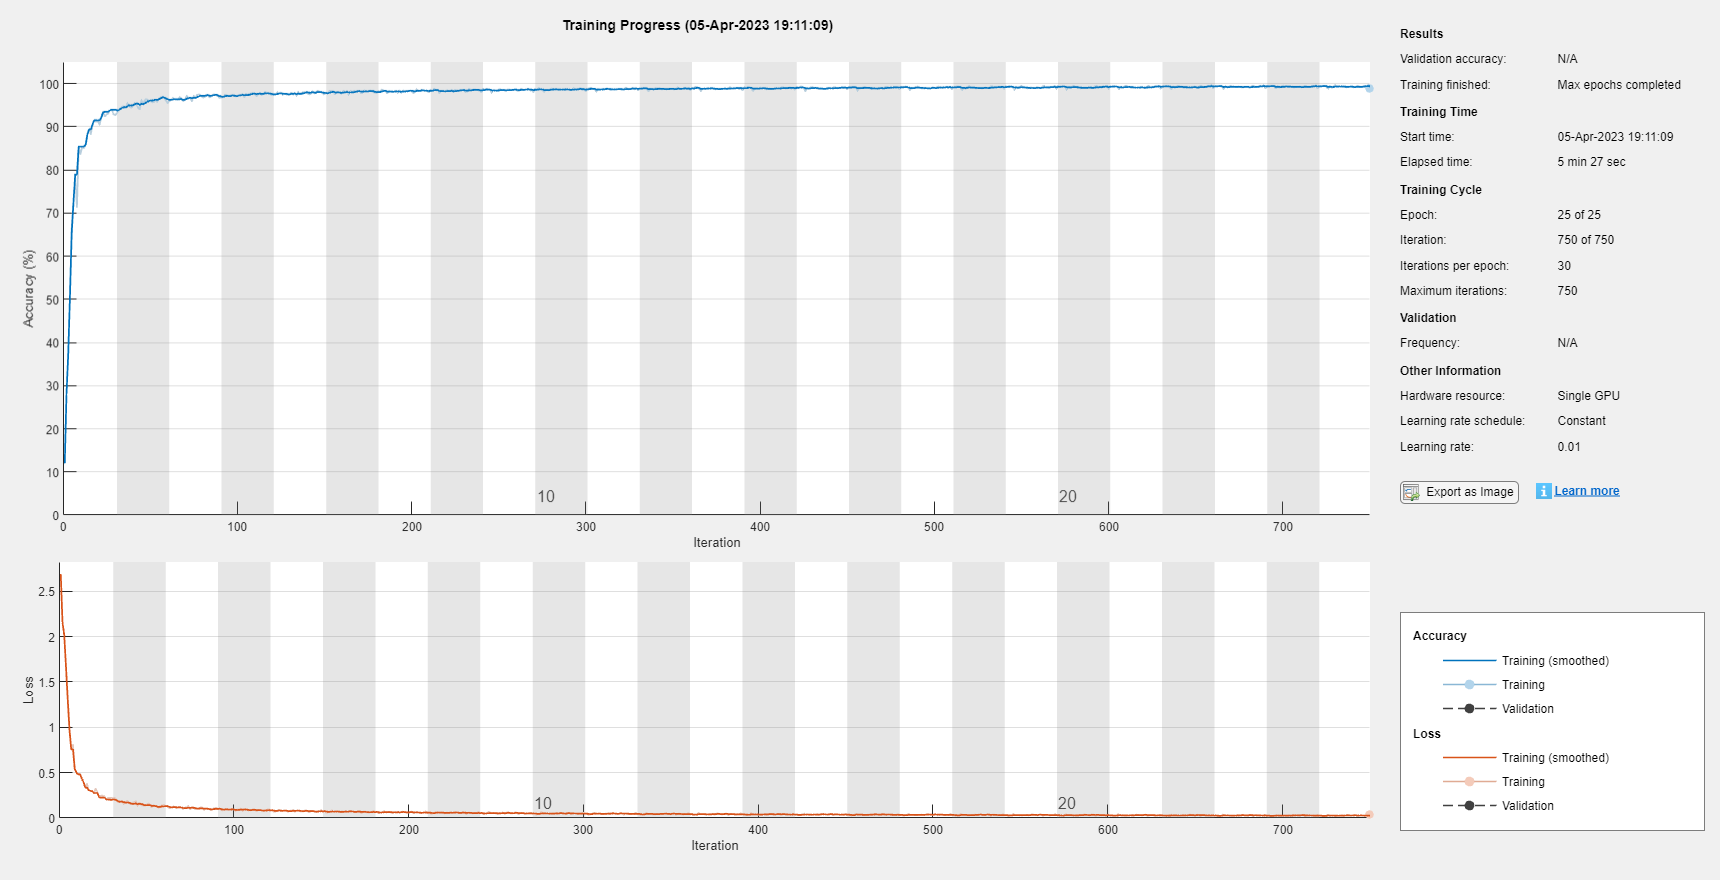

miniBatchSize = 2000;
options = trainingOptions( 'sgdm',...
    'MaxEpochs', 25,...
    'InitialLearnRate',0.01,...
    'MiniBatchSize', miniBatchSize,...
    'Plots', 'training-progress');

% Train the CNN
model = trainNetwork(Xtrain, LabelTrain, layers, options);

## Test the accuracy of the trained model on the test data

predLabelsTest = model.classify(Xtest);
accuracy = sum(predLabelsTest == LabelTest) / numel(LabelTest)

accuracy = 0.9905

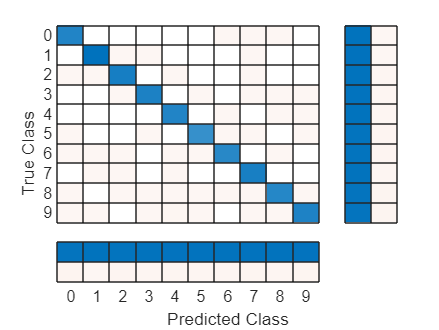


% Show confusion matrix in figure
[m, order] = confusionmat(LabelTest, predLabelsTest);
figure(1);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

## Test on a sample image

Set i to the index of the image choosen

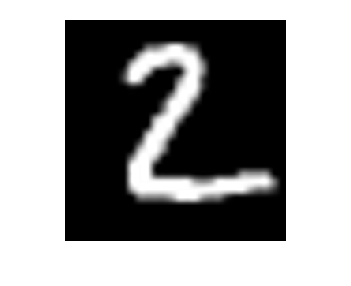

i = 2;
curimg = Xtest(:, :, i);
% We will copy and resize the image for demonstration purposes
figure(2);
imshow(imresize(curimg,10), [0 255]);

% Grab the ground truth and compare to our prediction, if correct the
% predicted label should be the same as the annotated one.
groundTruth = LabelTest(i);
predLabel = model.classify(curimg);
disp(append('Predicted label = ', string(predLabel),' vs. Ground Truth = ', string(groundTruth)))

Predicted label = 2 vs. Ground Truth = 2
